clearvars; close all; clc;

# Acoustic impedance closed box

2024-04-20, JVsound, J.G. Vermond

## Introduction

This livescript describes how the acoustic impedance of a closed box is calculated.

## Electric equivalent circuit

The circuit representing the close box is available as a [Simulink model](matlab:open('./simulink\closedbox2portnetwerk.slx')). See the diagram below.

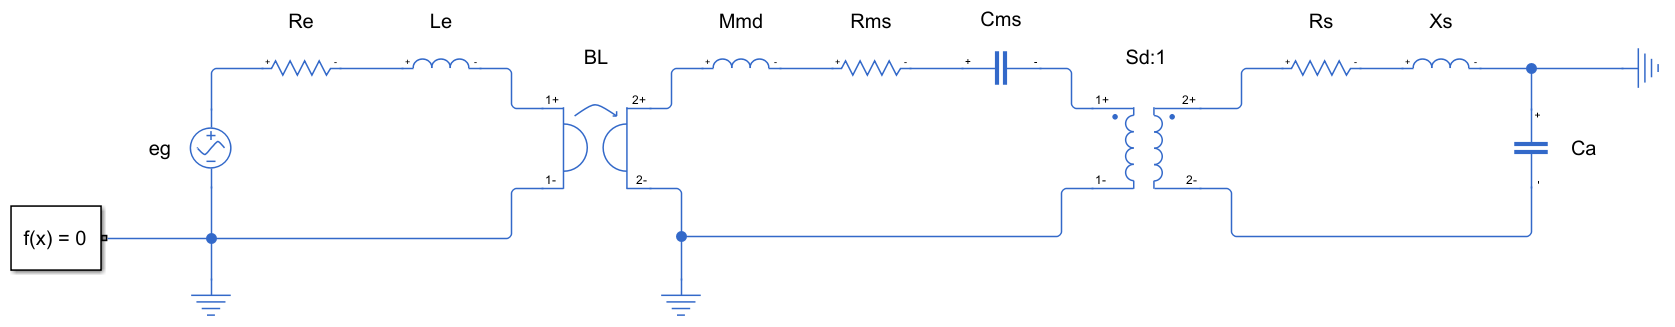

## Toolbox example

### Frequency range

% Frequency range in [Hz]:
f       = logspace(1,4,1e3);

% Convert to [rad/s]:
w       = 2*pi*f;

### Front

See the example "radiationimpedance" for further information. For the purpose of this livescript the impedance for the front side of the diaphragm is directly calculated:

% Calculate radius of diaphragm [m]:
a       = sqrt(1680e-4 / pi);

% Calculate radiation impedance:
zafront = acoustics.impedance.zarad(a,w);

### Rear

The volume of the closed box is treated as a compliance:

$p(t) = \frac{1}{C_A}\int Q(t)dt$,

where the acoustic compliance $C_A$ is:


$$C_A = \frac{V}{\rho_0c^2}$$


For a steady state equation, in the complex domain:


$$Z_A = -j\frac{1}{\omega C_A}$$


% Create a closed box object:
cb      = enclosure.closedbox;

% Set the volume [m3]:
cb.vol  = 200e-3;

% Acoustic impedance:
zarear  = cb.zarear(w);

### Figures

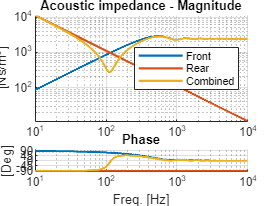

f1          = figure;

ax1         = subplot(3,1,1:2); hold on; grid on;
ax2         = subplot(3,1,3); hold on; grid on;
ax1.XScale  = "log";
ax2.XScale  = "log";
ax1.YScale  = "log";
ax2.YTick   = -90:45:90;
ax2.YLim    = [-100 100];

p1          = plot(ax1,f,abs(zafront),LineWidth=1.5);
p2          = plot(ax1,f,abs(zarear),LineWidth=1.5);
p3          = plot(ax1,f,abs(zafront + zarear),LineWidth=1.5);

p12         = plot(ax2,f,angle(zafront)*180/pi,LineWidth=1.5);
p22         = plot(ax2,f,angle(zarear)*180/pi,LineWidth=1.5);
p23         = plot(ax2,f,angle(zafront + zarear)*180/pi,LineWidth=1.5);

ax1.YLabel.String   = "[Ns/m^5]";
ax2.XLabel.String   = "Freq. [Hz]";
ax2.YLabel.String   = "[Deg]";

ax1.Title.String    = "Acoustic impedance - Magnitude";
ax2.Title.String    = "Phase";

legend(ax1,[p1 p2 p3],"Front","Rear","Combined",Location="east")

## Simulink example

% Frequency [Hz]:
f       = 100;

% Generator voltage [V]:
eg      = 2.83;

% Electrical part:
re      = 6;
le      = 2.2e-3;

% Gyrator:
bl      = 39;

% Mechanical part:
mmd     = .4118;
rms     = 15.3849;
cms     = 5.051e-5;

% Transformer:
sd      = .1680;

% Acoustic part:
rs      = 0;
xs      = 0;

ca      = 0;